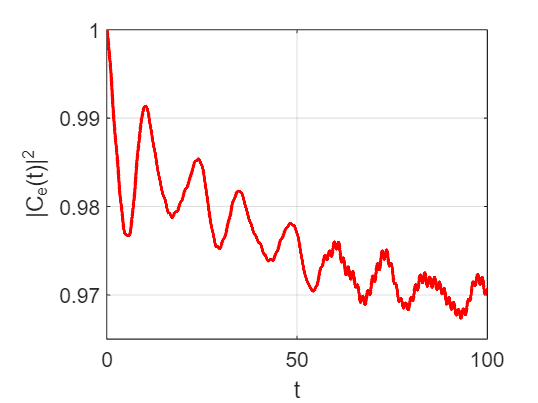

% Clear workspace, command window, and close all figures
clear;
clc;
close all;


% Parameters
N = 51; % Example value, you can change it
g = 0.1;   % Coupling strength g
J = 2;   % Coupling constant J
J_prime = 1; % Coupling constant J'
omega = 5; % Modulation frequency omega
Delta = - omega * 0.7;  % Detuning parameter Delta
V = 0.2;   % Modulation amplitude V
j_0 = (N-1)/2;

dt = 0.01;  % Time step for numerical integration
T = 100;   % Total simulation time
% Time vector
time = 0:dt:T;
num_steps = length(time);


% Define the Hamiltonian function
Ht = @(t) Hamilontian(t, N, J, J_prime, V, omega, g, Delta, j_0);

% Initialize the qubit in the excited state
psi_0 = zeros(2*N+1, 1);
psi_0(end) = 1;


% 调用runge_kutta_solver函数
psi_t = runge_kutta_timedependent(Ht, psi_0, time);



% Plot |C_e(t)|^2 vs time
figure;
plot(time, abs(psi_t(end, :)).^2, 'r', 'LineWidth', 1.5);
xlabel('t');
ylabel('|C_{e}(t)|^2');
grid on;

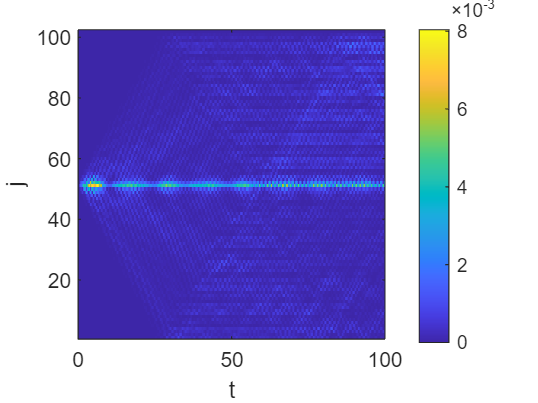



% Plot |B_j(t)|^2 as a heatmap
figure;
imagesc(time, 1:2*N, abs(psi_t(1:end-1, :)).^2);
colorbar;
xlabel('t');
ylabel('j');
set(gca, 'YDir', 'normal'); % Ensure y-axis is correctly oriented


% Define function for the derivative


function H = Hamilontian(t, N, J, J_prime, V, omega, g, Delta, j_0)
    v = 2 * V * cos(omega * t);
    % Create the Hamiltonian matrix
    H = zeros(2*N + 1);  % Include additional state for the qubit
    for i = 1:N-1

        H(2*i-1, 2*i) = J + v;
        H(2*i, 2*i-1) = J + v;

        H(2*i,2*i+1) = J_prime - v;
        H(2*i+1,2*i) = J_prime - v;
    end
    
    % Coupling the qubit to the left end of the SSH chain
    H(2*j_0+1, end) = g;
    H(end, 2*j_0+1) = g;
    H(end, end) = Delta;
end


